clear
close all
clc

定义参数和系统

b1 = -1.1; b2 = 0.6;
a = [1, b1, b2];
b = [b2, b1, 1];

计算和绘制零极点图、单位样值响应

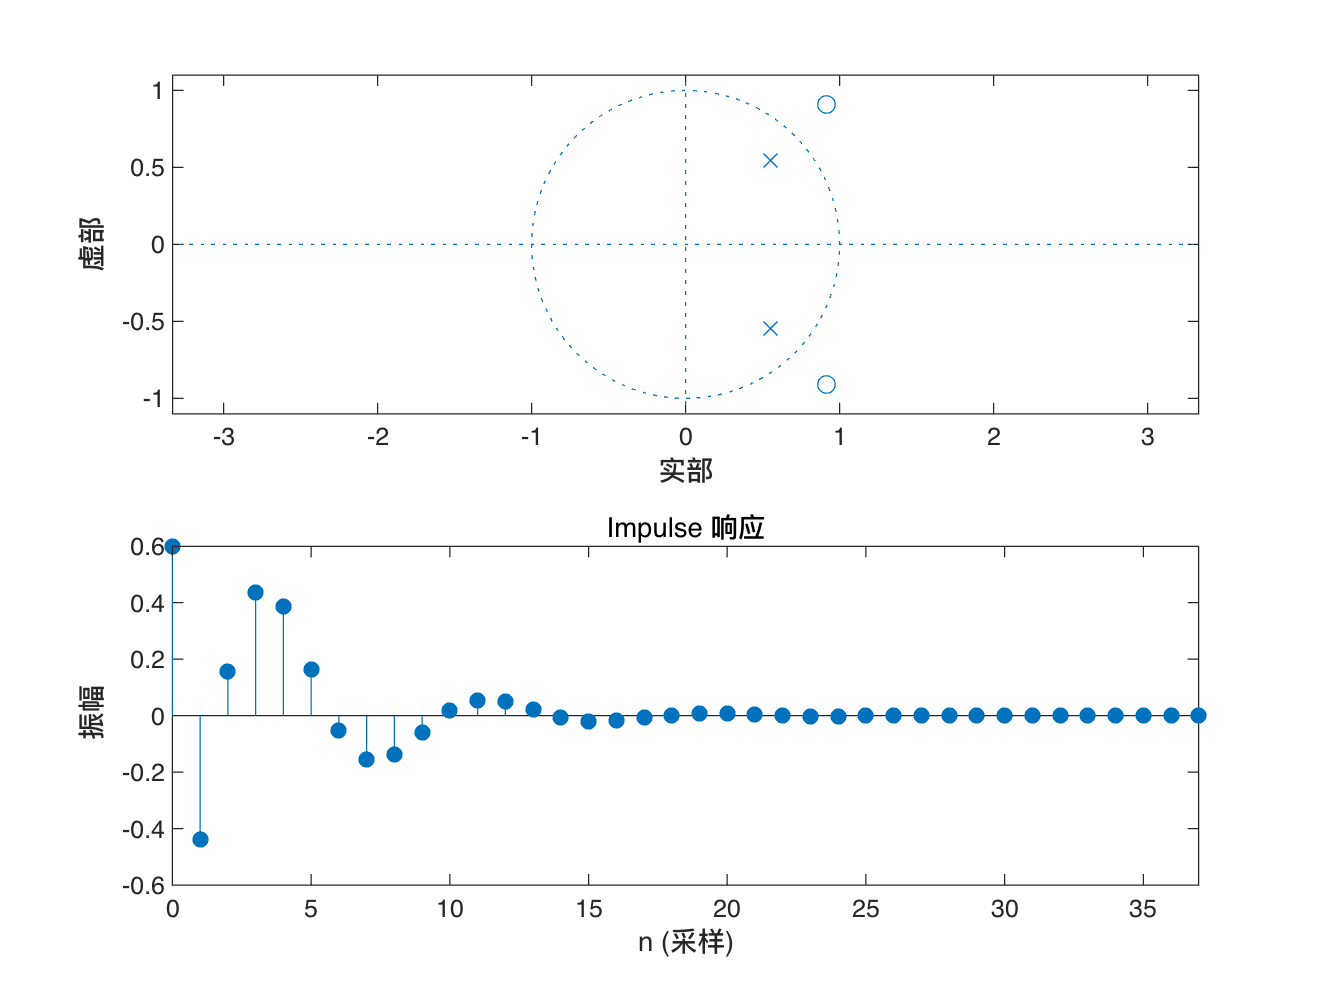

figure;
subplot(2,1,1), zplane(b,a);
subplot(2,1,2), impz(b,a);

计算和绘制幅频、相频响应

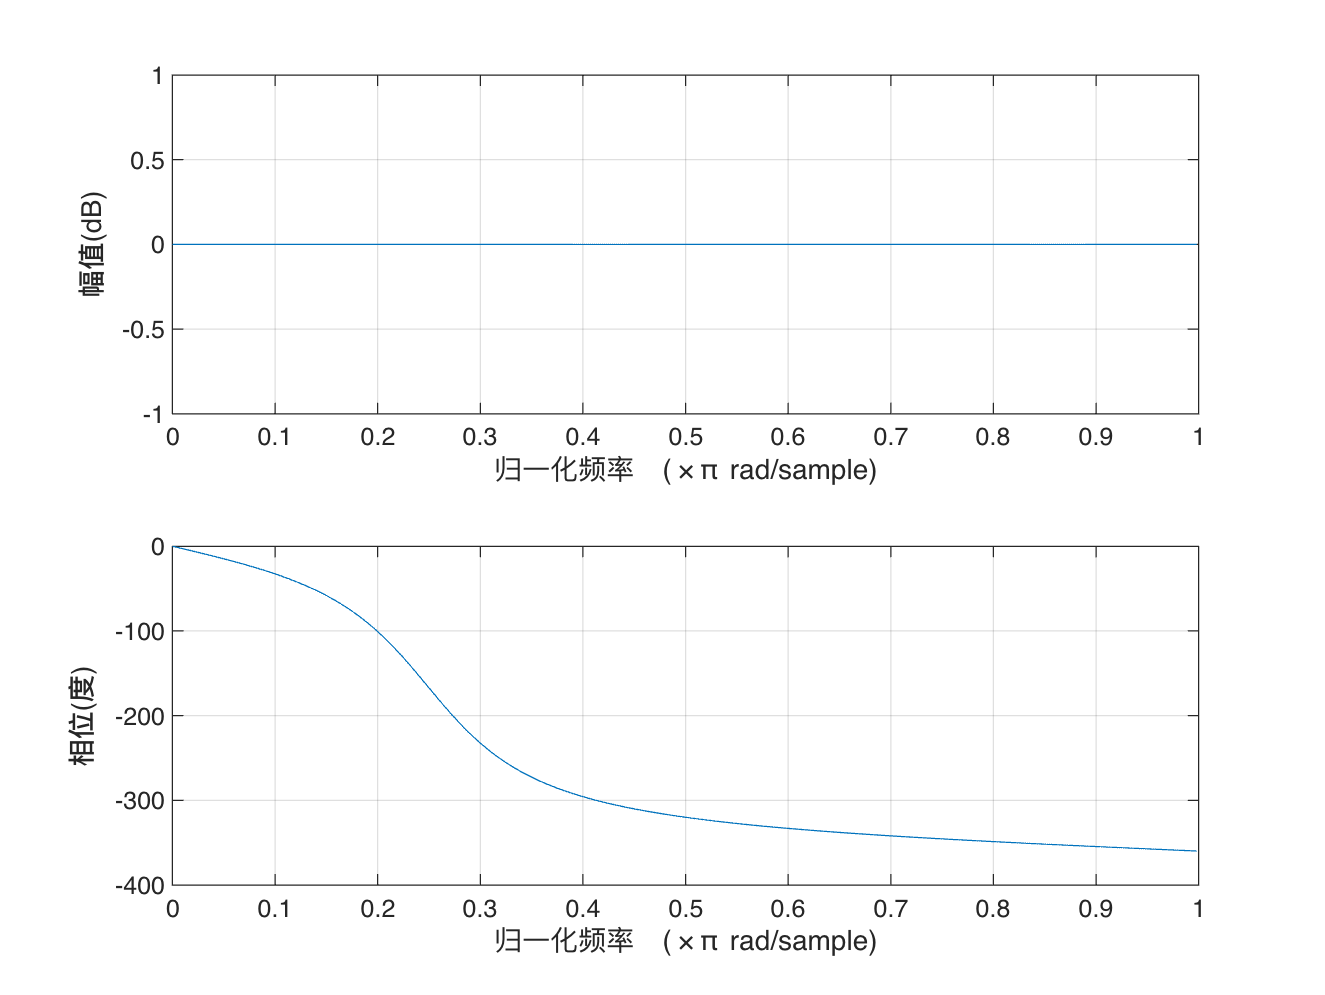

figure, freqz(b,a);

定义仿真时刻

n = [0:40]';

生成单频信号和同周期的矩形波

T = 10;
x1 = sin(2*pi*1/T*n);
x2 = mod(n,T)<(T/2);

过上述系统计算响应

y = filter(b,a,[x1,x2]);

绘图

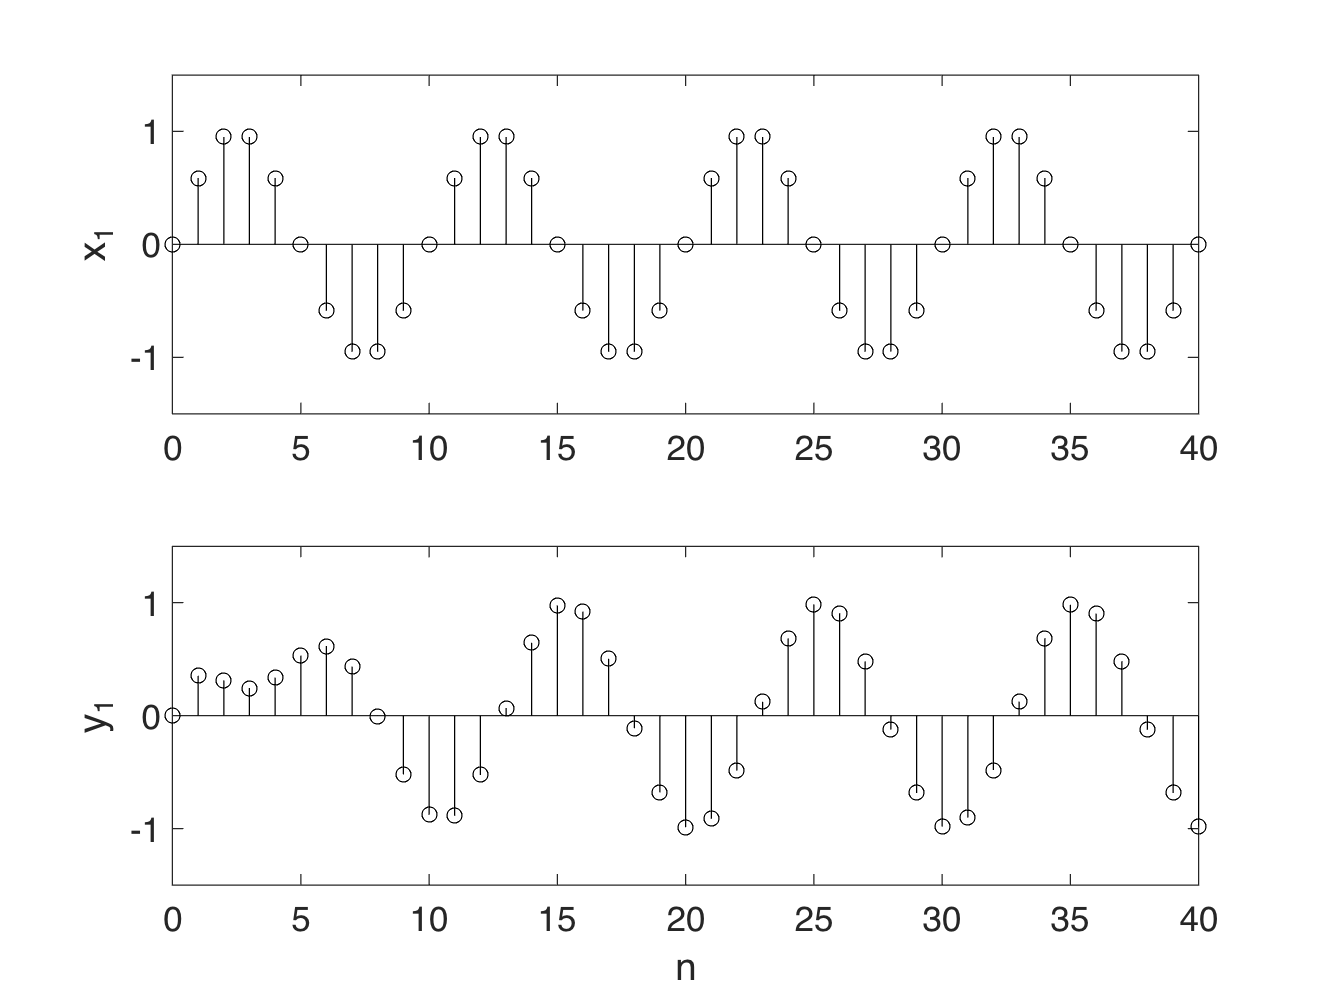

figure;
subplot(2,1,1), hold on, box on;
stem(n,x1,'k-');
ylabel('x_1','FontSize',14);
set(gca,'YLim',[-1.5,1.5],'FontSize',14);
subplot(2,1,2), hold on, box on;
stem(n,y(:,1),'k-');
xlabel('n','FontSize',14);
ylabel('y_1','FontSize',14);
set(gca,'YLim',[-1.5,1.5],'FontSize',14);

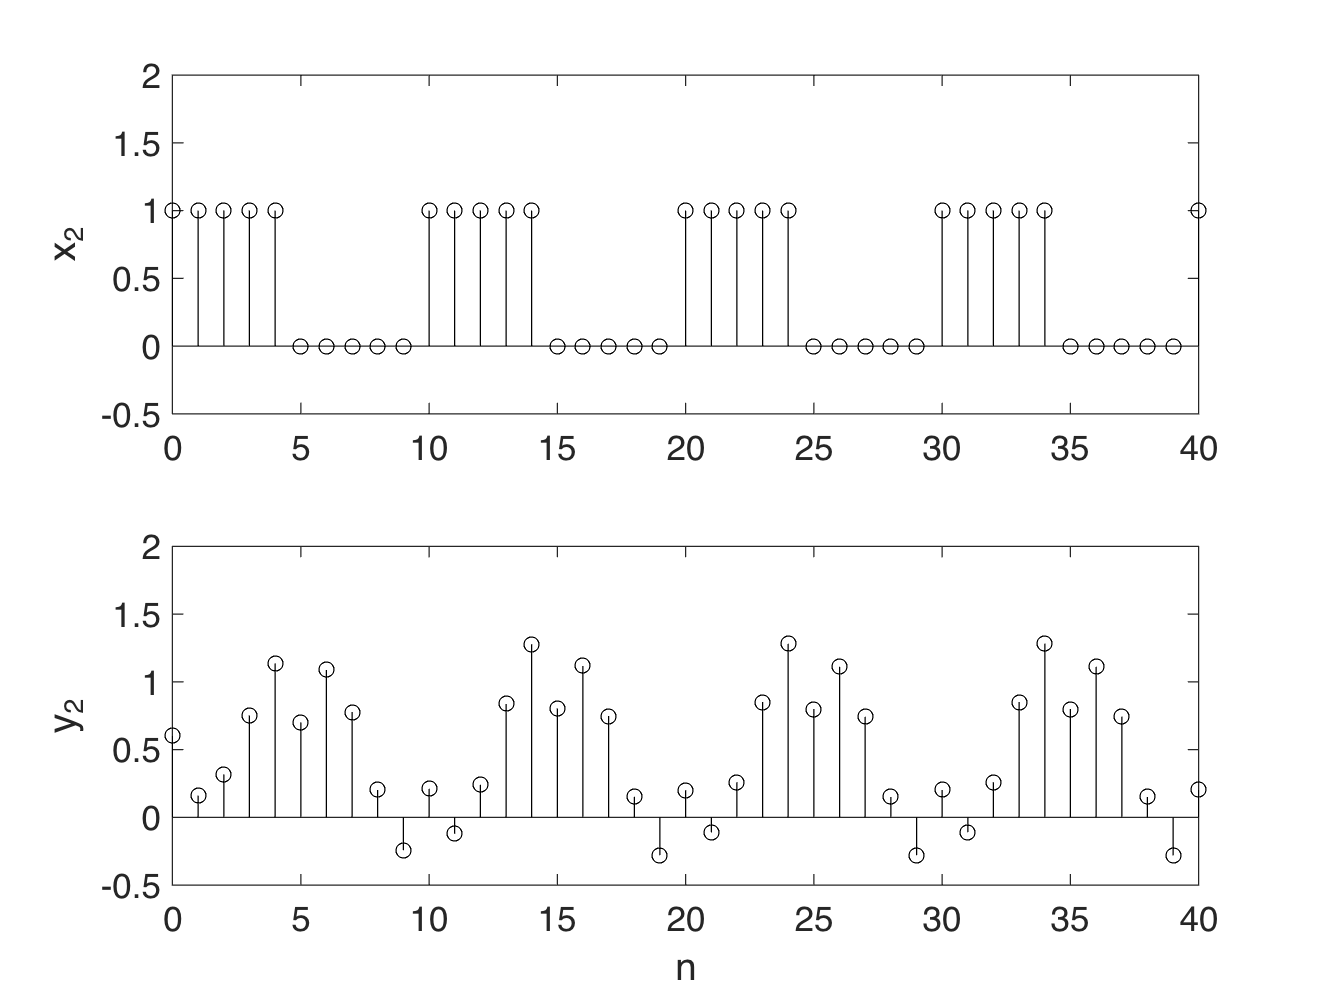


figure;
subplot(2,1,1), hold on, box on;
stem(n,x2,'k-');
ylabel('x_2','FontSize',14);
set(gca,'YLim',[-0.5,2],'FontSize',14);
subplot(2,1,2), hold on, box on;
stem(n,y(:,2),'k-');
xlabel('n','FontSize',14);
ylabel('y_2','FontSize',14);
set(gca,'YLim',[-0.5,2],'FontSize',14);

听听感觉

n = [0:16000]';
x = 0.5*(mod(n,10)<5);
y = filter(b,a,x);

sound([x;y]);
audiowrite('input.wav',x,8000);
audiowrite('output.wav',y,8000);